常数表

clc
clear

global k T q VT epsilon ni mu_n mu_p tau_n tau_p NA ND
k=1.3806505e-23;
T=300;
q=1.6021766209e-19;

VT=k*T/q; %热电势

epsilon0 = 8.854187817e-10; %介电常量，单位F/cm
epsilonr = 11.7;
epsilon = epsilonr * epsilon0;

ni = 1e10; %本征载流子浓度,cm^(-3)
mu_n = 1420; %迁移率
mu_p = 470; 

tau_n = 0.5e-6; %载流子复合寿命
tau_p = 0.5e-6;

定义基准值，更新物理量单位

nbase=1e16 

nbase = 1.0000e+16

Vbase=VT

Vbase = 0.0259

xbase=sqrt(epsilon*Vbase/(q*nbase))

xbase = 4.0885e-04

D0=VT;
tbase=xbase^2/D0

tbase = 6.4658e-06

jbase=q*D0*nbase/xbase

jbase = 0.1013


%更新
ni=ni/nbase

ni = 1.0000e-06

tau_n=tau_n/tbase

tau_n = 0.0773

tau_p=tau_p/tbase

tau_p = 0.0773

初始化，定义二极管

cycles = 1

err = 95.3754

cycles = 2

err = 467.1817

cycles = 3

err = 229.1604

cycles = 4

err = 372.5531

cycles = 5

err = 179.5474

cycles = 6

err = 18.7740

cycles = 7

err = 13.4949

cycles = 8

err = 5.5073

cycles = 9

err = 2.2333

cycles = 10

err = 0.5257

cycles = 11

err = 1.0408

cycles = 12

err = 0.2453

cycles = 13

err = 0.5948

cycles = 14

err = 0.2777

cycles = 15

err = 0.2170

cycles = 16

err = 0.1552

cycles = 17

err = 0.1989

cycles = 18

err = 0.0968

cycles = 19

err = 0.0975

cycles = 20

err = 0.0046

cycles = 21

err = 3.0925e-06

cycles = 22

err = 3.5672e-07

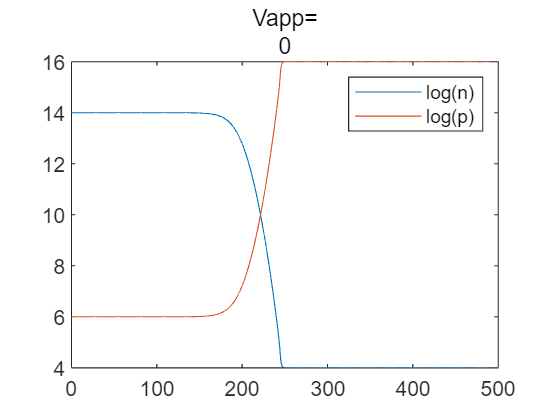

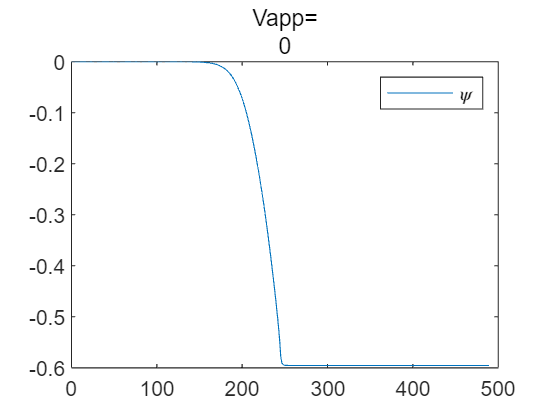

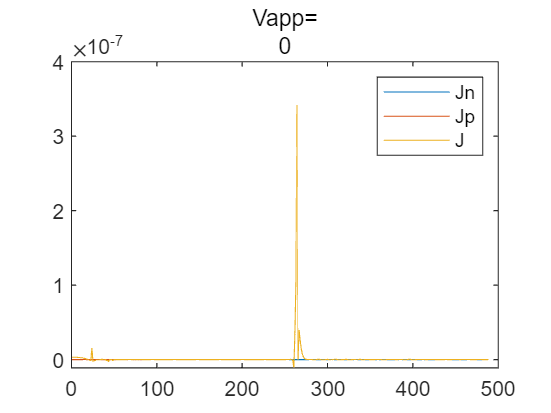

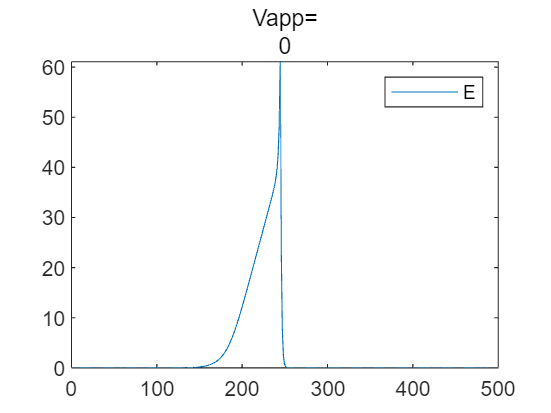

cycles = 1

err = 230.5438

cycles = 2

err = 0.6071

cycles = 3

err = 0.0034

cycles = 4

err = 6.4416e-07

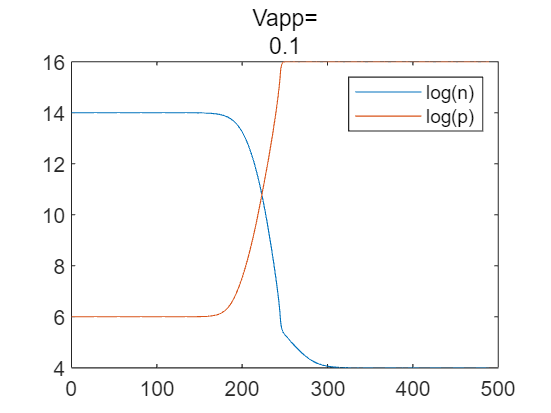

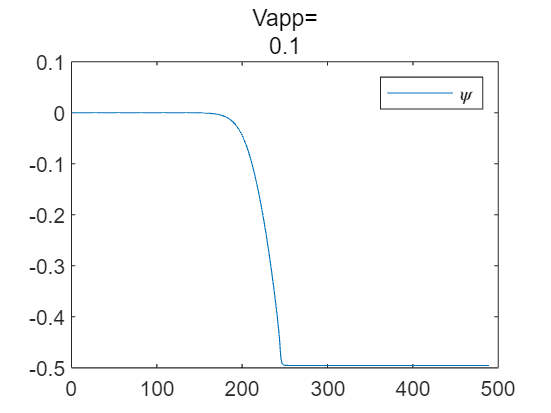

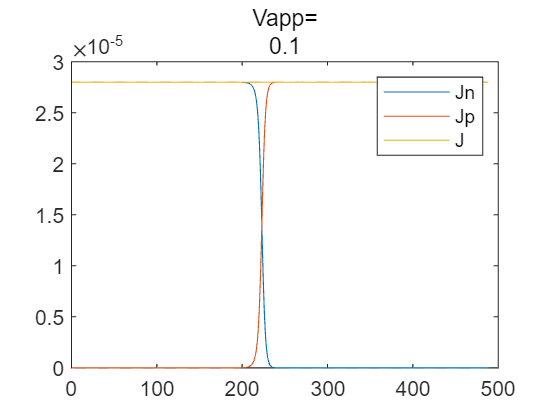

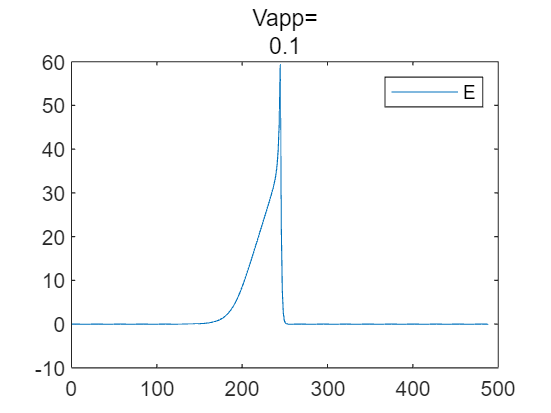

cycles = 1

err = 230.1611

cycles = 2

err = 0.6214

cycles = 3

err = 0.0073

cycles = 4

err = 8.1420e-06

cycles = 5

err = 4.0255e-09

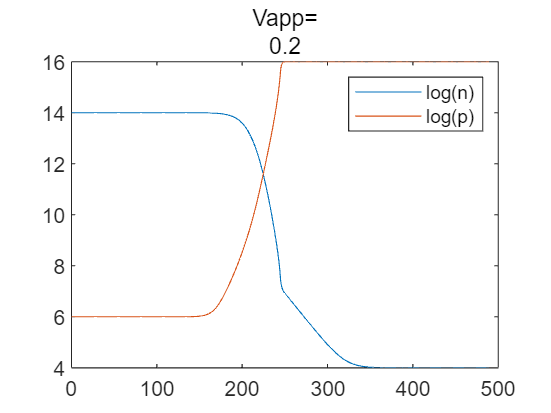

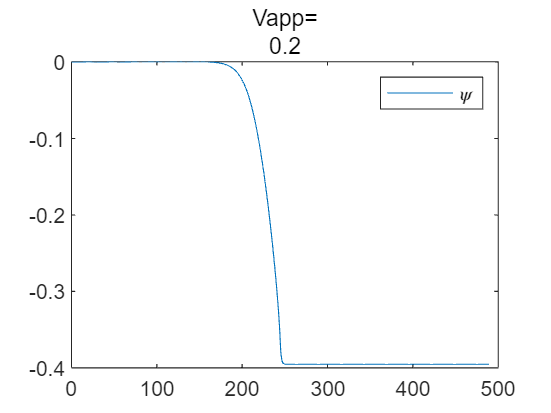

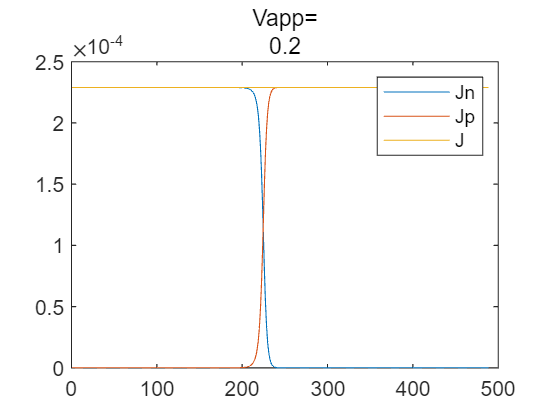

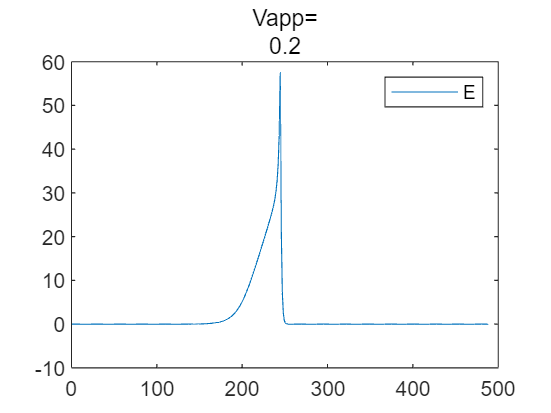

cycles = 1

err = 229.9243

cycles = 2

err = 0.8570

cycles = 3

err = 0.0282

cycles = 4

err = 1.2157e-05

cycles = 5

err = 1.4787e-09

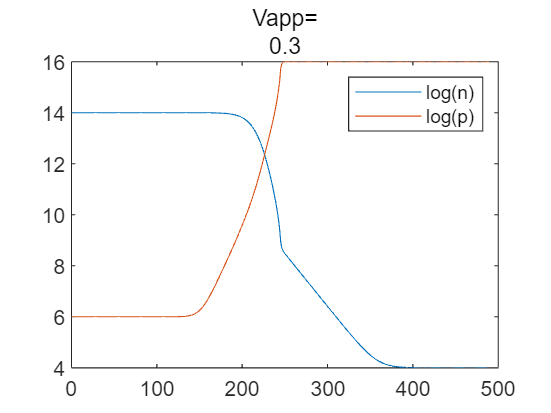

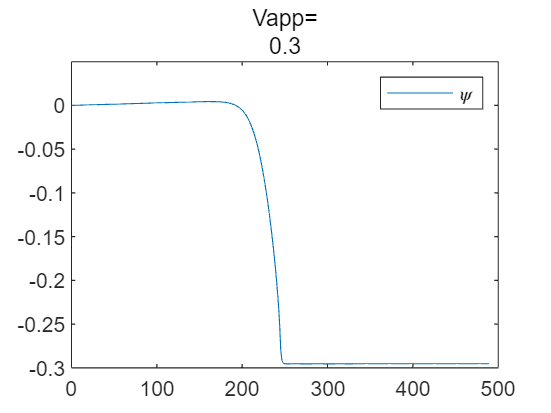

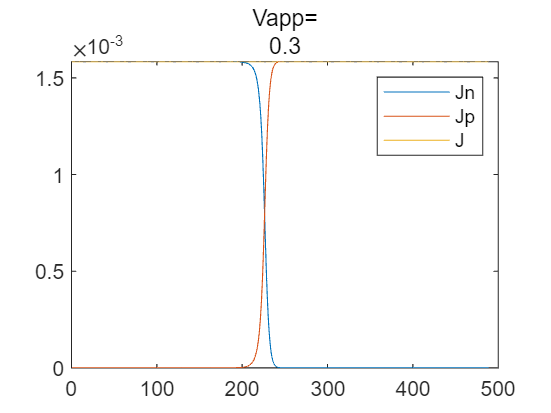

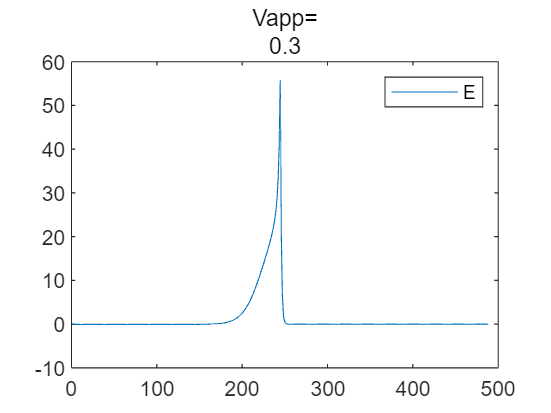

cycles = 1

err = 230.7533

cycles = 2

err = 3.2222

cycles = 3

err = 0.1400

cycles = 4

err = 2.6429e-04

cycles = 5

err = 1.0417e-09

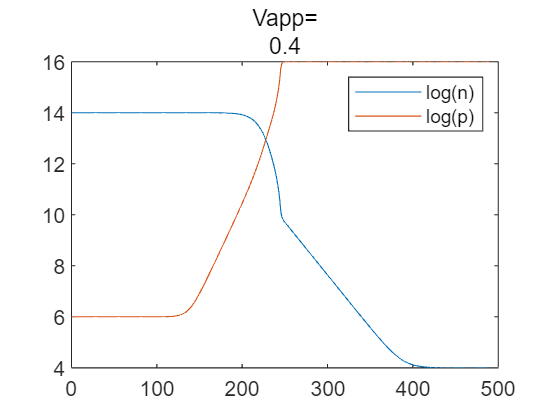

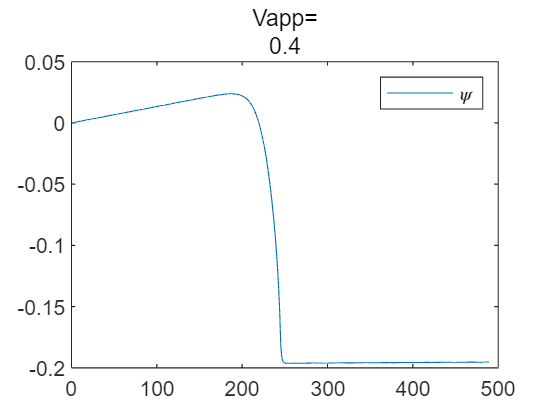

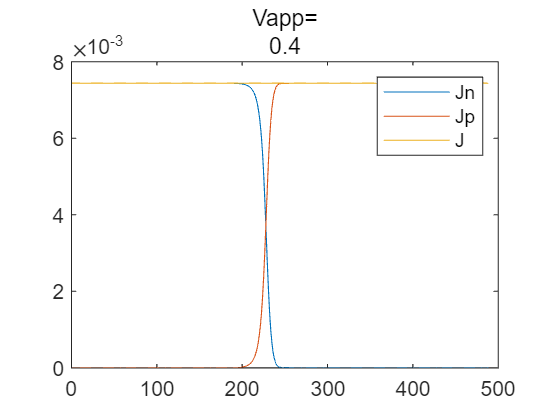

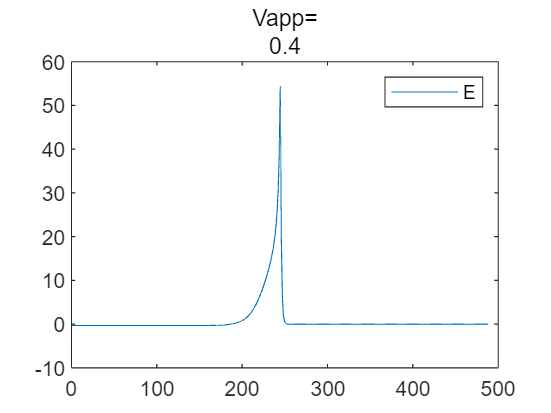

cycles = 1

err = 234.0754

cycles = 2

err = 3.5256

cycles = 3

err = 0.0337

cycles = 4

err = 1.2834e-04

cycles = 5

err = 9.6645e-11

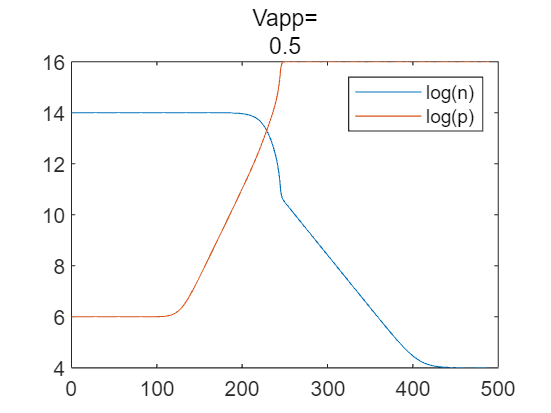

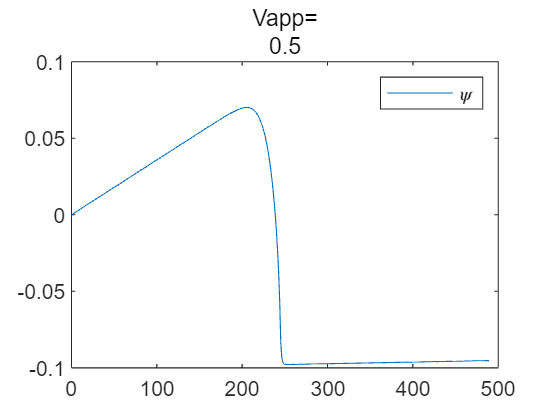

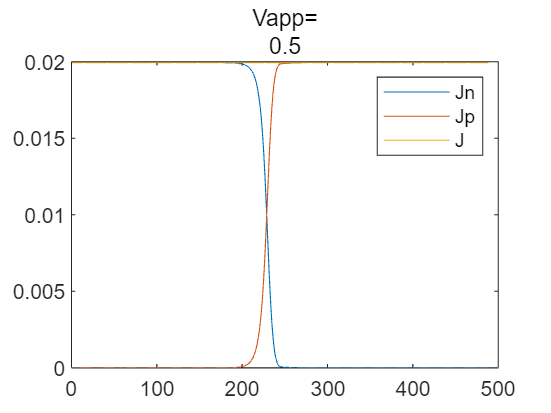

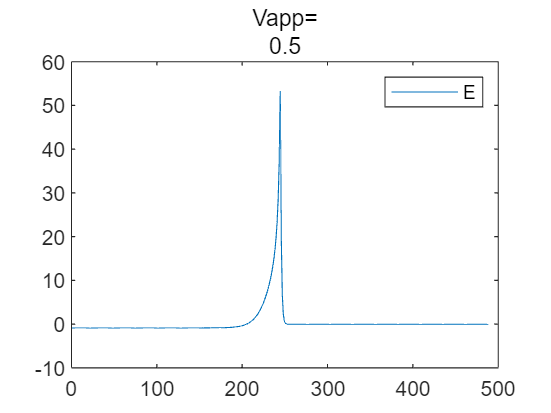

%doping, cm^{-3}
ND = 1e14/nbase; NA = 1e16/nbase;
%length, cm
xn = 0.0015/xbase; xp = 0.0015/xbase;
L = xn + xp;
%voltage, V
Vapp = -0.1/Vbase;

%定义网格，均匀的
N = 400;
dx = L / (N - 1);
x=0:dx:L;
%定义解向量
sln=zeros(N,3);
Jav1=[]; %将所有电流的解汇总
sln_output=[]; %将每次迭代的结果汇总
sln_order=[]; %每次迭代的标号记录
for V=0:0.1:0.5
    Vapp=V/Vbase;
    %边界条件
    %n0, p0, psi0
    sln(1,1) = ND / 2 + sqrt(ND^2 / 4 + ni^2);
    sln(1,2) = ni^2 / sln(1,1);
    sln(1,3) = asinh(ND / (2 * ni));
    %nL, pL, psiL
    sln(N,2) = NA / 2 + sqrt(NA^2 / 4 + ni^2);
    sln(N,1) = ni^2 / sln(N,2);
    sln(N,3) = Vapp - asinh(NA / (2 * ni));
    
    %设定初始猜测解
    if abs(V)<0.1
        for i=2:N/2
            sln(i,1)=ND;
            sln(i,2)=ni^2/sln(i,1);
            sln(i,3)=sln(1,3)+(sln(N,3)-sln(1,3))/(N-1)*(i-1);
        end
        for i=(N/2+1):(N-1)
            sln(i,2)=NA;
            sln(i,1)=ni^2/sln(i,2);
            sln(i,3)=sln(1,3)+(sln(N,3)-sln(1,3))/(N-1)*(i-1);
        end
    end

    %开始迭代求解
    err=1;
    cycles=0;
    %dsln=1;
    while abs(err)>1e-6
        ds=genDSolution(sln,N,dx);
        b=reshape(ds(2:(N-1),:)',[3*(N-2),1]);
        J=genJacobi(sln,N,dx);
        
        dsln=J^(-1)*b;
    
        dsln=reshape(dsln,[3,N-2]);
        dsln=[0 0 0; dsln'; 0 0 0];
        sln=sln+dsln;
        cycles=cycles+1;

        cycles
        %condJ=cond(J)
        %err=norm(dsln)/norm(sln)
        err=norm(dsln)

        sln_output=[sln_output;reshape(sln,[1,3*N])];
        sln_order=[sln_order;V,cycles,err];
    
    end
    
    sln(:,3)=sln(:,3)-sln(1,3);
    %绘图
    figure();
    plot(x,log10(nbase*sln(:,1)))
    hold on
    plot(x,log10(nbase*sln(:,2)))
    hold off
    legend("log(n)","log(p)");
    title(["Vapp=",num2str(V)])

    figure();
    plot(x,VT*sln(:,3))
    legend("\psi")
    title(["Vapp=",num2str(V)])

    %绘制电流
    xj=(0.5:N-1.5)*dx;

    jns=[];
    jps=[];
    for i=1:N-1
        jns=[jns;jbase*Jn(dx, sln(i+1,1), sln(i,1), sln(i+1,3), sln(i,3))];
        jps=[jps;jbase*Jp(dx, sln(i+1,2), sln(i,2), sln(i+1,3), sln(i,3))];
    end
    
    figure();
    plot(xj,-jns,xj,-jps,xj,-(jns+jps));
    legend("Jn","Jp","J")
    title(["Vapp=",num2str(V)])

    Jav1=[Jav1;-mean(jns+jps)];
    
    %绘制电场
    Es=[];
    for i=1:N-1
        dE=(sln(i,3)-sln(i+1,3))/dx*VT/xbase;
        Es=[Es;dE];
    end
    figure();
    plot(xj,Es);
    legend("E");
    title(["Vapp=",num2str(V)])
end

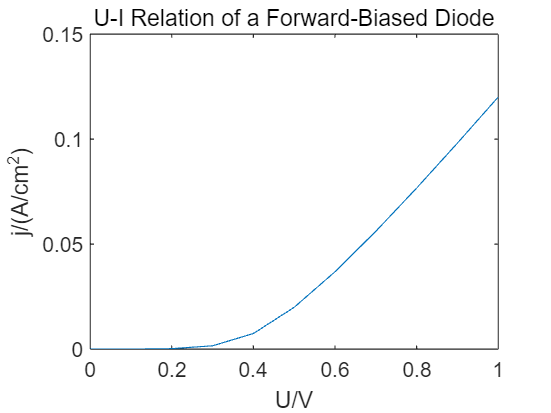

figure();
plot(0:0.1:1,Jav)
xlabel("U/V")
ylabel("j/(A/cm^2)")
title("U-I Relation of a Forward-Biased Diode")

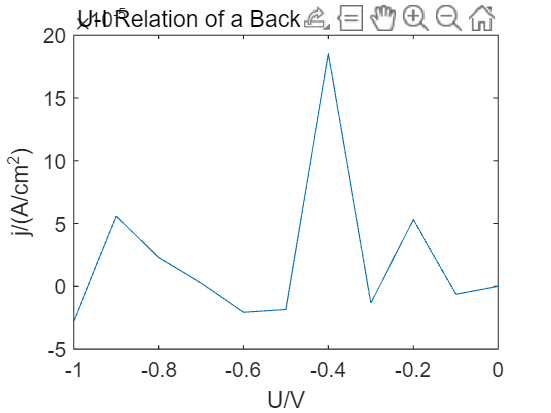

figure();
plot(0:-0.1:-1,Jav1)
xlabel("U/V")
ylabel("j/(A/cm^2)")
title("U-I Relation of a Backward-Biased Diode")

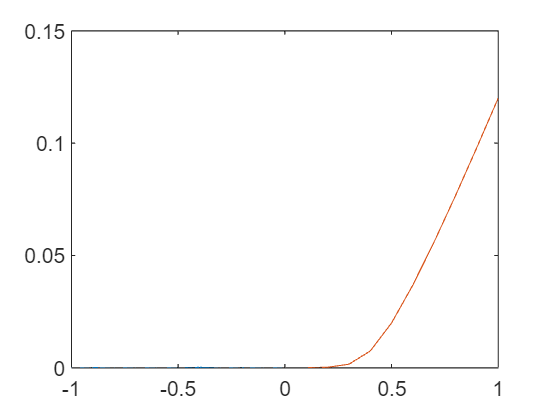

figure();
plot(0:-0.1:-1,Jav1)
hold on
plot(0.1:0.1:1,Jav(2:end))
hold off

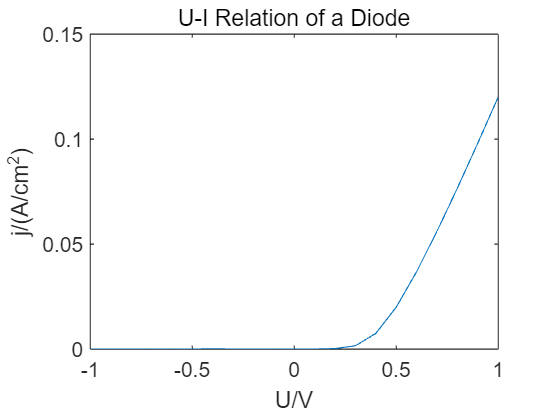


Jav_total=[flip(Jav1);Jav(2:end)];
U=-1:0.1:1;
plot(U,Jav_total)
xlabel("U/V")
ylabel("j/(A/cm^2)")
title("U-I Relation of a Diode")

函数表

function b=Bernoulli(x)
    if abs(x) < 1e-10  
        b=1.0;
    elseif x > 100
        b=0;
    elseif x < -30 
        b=-x;
    else 
        b = x / (exp(x) - 1);
    end
end

function db=dBernoulli(x)
    if abs(x)<1e-5 
        db=-0.5;
    elseif x>100
        db=0;
    elseif x<-30
        db=-1;
    else
        db=(exp(x)*(1-x)-1)/(exp(x)-1)^2;
    end
end

%电子和空穴电流方程，'w''m''e'分别代表离散格点的左中右
function j=Jn(dx, ne, nm, psie, psim)
    global mu_n;
    j = mu_n / dx * (ne * Bernoulli(psie - psim) - nm * Bernoulli(psim - psie));
end
function j=Jp(dx, pe, pm, psie, psim)
    global mu_p;
    j = mu_p / dx * (pm * Bernoulli(psie - psim) - pe * Bernoulli(psim - psie));
end

%SRH复合模型
function r=R_SRH(n,p)
    global ni tau_n tau_p;
    r=(n * p - ni^2) / (tau_p * (n + ni) + tau_n * (p + ni));
end


% 泊松方程离散化, N=ND-NA
function f=Fpsi(dx,n,p,N,psiw,psim,psie)
    f=psiw-2*psim+psie+(N+p-n)*dx^2;
end
% 载流子（电子）守恒
function f=Fn(dx,nw,nm,ne,pm,psiw,psim,psie)
    f=Jn(dx,ne,nm,psie,psim)-Jn(dx,nm,nw,psim,psiw)...
        -dx*R_SRH(nm,pm);
end
% 载流子（空穴）守恒
function f=Fp(dx,nm,pw,pm,pe,psiw,psim,psie)
    f=Jp(dx,pe,pm,psie,psim)-Jp(dx,pm,pw,psim,psiw)...
        +dx*R_SRH(nm,pm);
end

微分表

function d=dRdn(n,p)
    global ni mu_n mu_p tau_n tau_p;
    d=(tau_n*p+tau_p*ni)*(p+ni)/(tau_p*(n+ni)+tau_n*(p+ni))^2;
end
function d=dRdp(n,p)
    global ni mu_n mu_p tau_n tau_p;
    d=(tau_p*n+tau_n*ni)*(n+ni)/(tau_p*(n+ni)+tau_n*(p+ni))^2;
end

function d=dJn1(dx,ne,nm,psie,psim)
    global mu_n;
    d= mu_n / dx * Bernoulli(psie - psim);
end
function d=dJn2(dx,ne,nm,psie,psim)
    global mu_n;
    d= - mu_n / dx * Bernoulli(psim - psie);
end
function d=dJn3(dx,ne,nm,psie,psim)
    global mu_n;
    temp = (psie - psim);
	d= mu_n / dx * (ne * dBernoulli(temp) + nm * dBernoulli(-temp));
end
function d=dJn4(dx,ne,nm,psie,psim)
    global mu_n;
    temp = (psie - psim);
	d= - mu_n / dx * (ne * dBernoulli(temp) + nm * dBernoulli(-temp));
end

function d=dJp1(dx,pe,pm,psie,psim)
    global mu_p;
    d= - mu_p / dx * Bernoulli(psim - psie);
end
function d=dJp2(dx,pe,pm,psie,psim)
    global mu_p;
    d= mu_p / dx * Bernoulli(psie - psim);
end
function d=dJp3(dx,pe,pm,psie,psim)
    global mu_p;
    temp = (psie - psim);
	d= mu_p / dx * (pm * dBernoulli(temp) + pe * dBernoulli(-temp));
end
function d=dJp4(dx,pe,pm,psie,psim)
    global mu_p;
    temp = (psie - psim);
	d= - mu_p / dx * (pm * dBernoulli(temp) + pe * dBernoulli(-temp));
end

误差函数生成

function ds=genDSolution(s,N,dx)
    global NA ND
    ds=zeros(N,3);
    for i=2:N-1
        nw=s(i-1,1); nm=s(i,1); ne=s(i+1,1);
        pw=s(i-1,2); pm=s(i,2); pe=s(i+1,2);
        psiw=s(i-1,3); psim=s(i,3); psie=s(i+1,3);

        ds(i,1)=Fn(dx,nw,nm,ne,pm,psiw,psim,psie);
        ds(i,2)=Fp(dx,nm,pw,pm,pe,psiw,psim,psie);
        if i<=N/2
            ds(i,3)=Fpsi(dx,nm,pm,ND,psiw,psim,psie);
        else
            ds(i,3)=Fpsi(dx,nm,pm,-NA,psiw,psim,psie);
        end
    end
    ds=-ds;
end

雅可比矩阵生成

function J=genJacobi(s,N,dx)
    J=zeros(3*(N-2),3*(N-2));
    for i=2:N-1
        nw=s(i-1,1); nm=s(i,1); ne=s(i+1,1);
        pw=s(i-1,2); pm=s(i,2); pe=s(i+1,2);
        psiw=s(i-1,3); psim=s(i,3); psie=s(i+1,3);

        %Fn的微分
        if i>2
            J(3*(i-2)+1,3*(i-3)+1)=-dJn2(dx,nm,nw,psim,psiw); %nw
            J(3*(i-2)+1,3*(i-3)+3)=-dJn4(dx,nm,nw,psim,psiw); %psiw
        end

        J(3*(i-2)+1,3*(i-2)+1)= dJn2(dx,ne,nm,psie,psim) - dJn1(dx,nm,nw,psim,psiw)...
            - dx * dRdn(nm, pm); %nm
        J(3*(i-2)+1,3*(i-2)+3)=dJn4(dx,ne,nm,psie,psim)-dJn3(dx,nm,nw,psim,psiw); %psim

        if i<N-1
            J(3*(i-2)+1,3*(i-1)+1)=dJn1(dx,ne,nm,psie,psim); %ne
            J(3*(i-2)+1,3*(i-1)+3)=dJn3(dx,ne,nm,psie,psim); %psie
        end

        J(3*(i-2)+1,3*(i-2)+2)=-dx * dRdp(nm, pm); %pm
			
        %Fp的微分
        J(3*(i-2)+2,3*(i-2)+1)=dx*dRdn(nm,pm); %nm
        if i>2
            J(3*(i-2)+2,3*(i-3)+2)=-dJp2(dx,pm,pw,psim,psiw); %pw
            J(3*(i-2)+2,3*(i-3)+3)=-dJp4(dx,pm,pw,psim,psiw); %psiw
        end
        J(3*(i-2)+2,3*(i-2)+2)=dJp2(dx,pe,pm,psie,psim)-dJp1(dx,pm,pw,psim,psiw)...
            +dx*dRdp(nm,pm); %pm
        J(3*(i-2)+2,3*(i-2)+3)=dJp4(dx,pe,pm,psie,psim)-dJp3(dx,pm,pw,psim,psiw); %psim
        if i<N-1
            J(3*(i-2)+2,3*(i-1)+2)=dJp1(dx,pe,pm,psie,psim); %pe
            J(3*(i-2)+2,3*(i-1)+3)=dJp3(dx,pe,pm,psie,psim); %psie
        end

		%Fpsi的微分
        J(3*(i-2)+3,3*(i-2)+1)=-dx^2; %nm
        J(3*(i-2)+3,3*(i-2)+2)=dx^2; %pm
        J(3*(i-2)+3,3*(i-2)+3)=-2; %psim
        if i>2
            J(3*(i-2)+3,3*(i-3)+3)=1; %psiw
        end
        if i<N-1
            J(3*(i-2)+3,3*(i-1)+3)=1; %psie
        end
    end
end

		

		